# Theory

`For the unsteady state equation we have the following`


$$\frac{\partial\xi}{\partial t} + \frac{\partial^2\xi}{\partial x^2} + \frac{\partial^2\xi}{\partial y^2} = 0$$


`Similar to 1(a) we replace the partial derivatives with their finite difference formulas. Using central difference in space and forward difference in time we get`


$$\frac{\Xi_{i,j}^{n+1} - \Xi_{i,j}^{n}}{\Delta t} + \frac{\Xi_{i-1,j}^{n} - 2\Xi_{i,j} +\Xi_{i+1,j}^{n}}{(\Delta x)^2} + \frac{\Xi_{i,j-1}^{n} - 2\Xi_{i,j} +\Xi_{i,j+1}^{n}}{(\Delta y)^2} = 0 		\\
\Xi_{i,j}^{n+1} = \Xi_{i,j}^{n} + \frac{\Delta t}{(\Delta x)^2}\left(\Xi_{i-1,j}^{n} - 2\Xi_{i,j} +\Xi_{i+1,j}^{n}\right) + \frac{\Delta t}{(\Delta y)^2}\left(\Xi_{i,j-1}^{n} - 2\Xi_{i,j} +\Xi_{i,j+1}^{n}\right)$$


clear 
clc
close all

%spacesteps and meshgrid
dx = 0.1;
dy = 0.05;
[X, Y] = meshgrid(0:dx:1, 0:dy:1);

%timestep
dt = 0.001;
final_time = 0.250;
n = final_time/dt + 1;

%solution matrix with third dimension for time
Z = zeros(1/dy+1,1/dx+1,n);
Z(end,:,:) = 1;

for t = 1:n-1
    for i = 2:1/dx
        for j = 2:1/dy
            Z(j,i,t+1) = Z(j,i,t) + (dt/(dx^2)) * (Z(j,i+1,t) - 2*Z(j,i,t) + Z(j,i-1,t)) + (dt/(dy^2)) * (Z(j+1,i,t) - 2*Z(j,i,t) + Z(j-1,i,t));
        end
    end
end

# Plotting

Animation for each time

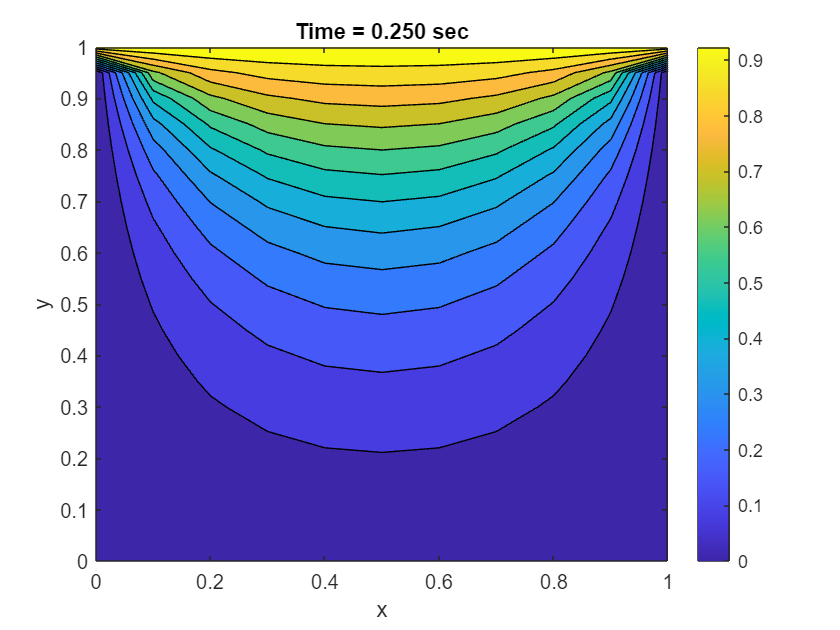

%plot at each time step
figure (1);
for t = 1:n
    contourf(X,Y,Z(:,:,t),12);
    colorbar
    str = sprintf('Time = %.3f sec', t*dt-dt);
    title(str);
    xlabel('x')
    ylabel('y')
    pause(0.005)
end

Plot for Absolute error

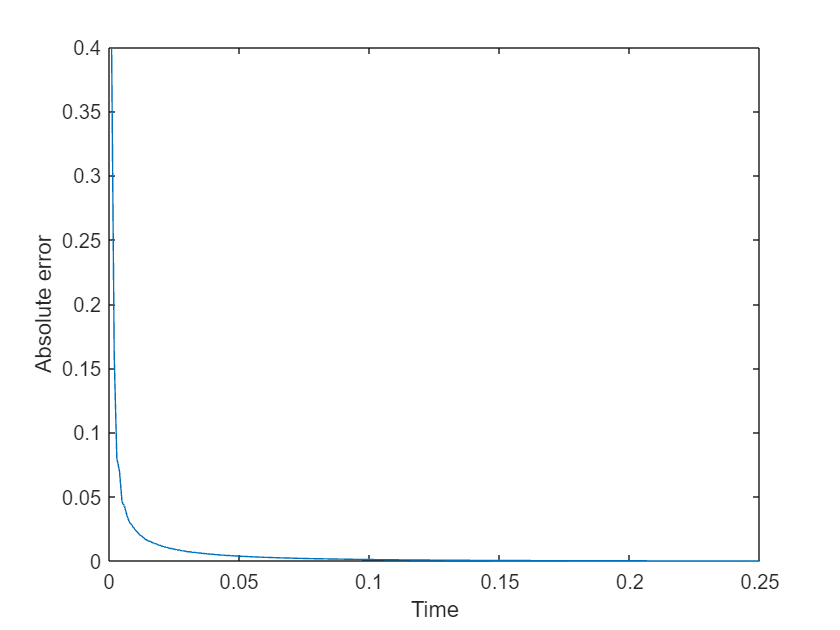

error = zeros(1,n-1);
for i = 1:n-1
    error(i) = max(abs(Z(:,:,i+1) - Z(:,:,i)), [], "all");
end

%error plot
figure (2);
plot(0.001:0.001:0.25, error)
xlabel('Time');
ylabel('Absolute error');

Contour at 4 different times for report

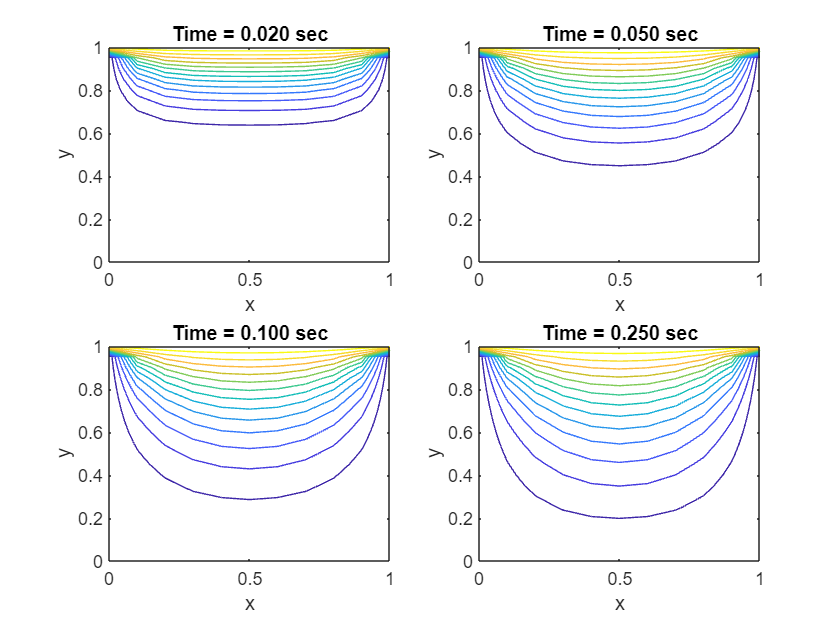

figure (3)
subplot(2,2,1)
contour(X,Y,Z(:,:,21),13)
str = sprintf('Time = %.3f sec', 0.02);
title(str);
xlabel('x')
ylabel('y')

subplot(2,2,2)
contour(X,Y,Z(:,:,51),13)
str = sprintf('Time = %.3f sec', 0.05);
title(str);
xlabel('x')
ylabel('y')

subplot(2,2,3)
contour(X,Y,Z(:,:,101),13)
str = sprintf('Time = %.3f sec', 0.1);
title(str);
xlabel('x')
ylabel('y')

subplot(2,2,4)
contour(X,Y,Z(:,:,251),13)
str = sprintf('Time = %.3f sec', 0.25);
title(str);
xlabel('x')
ylabel('y')

Slider for user interaction

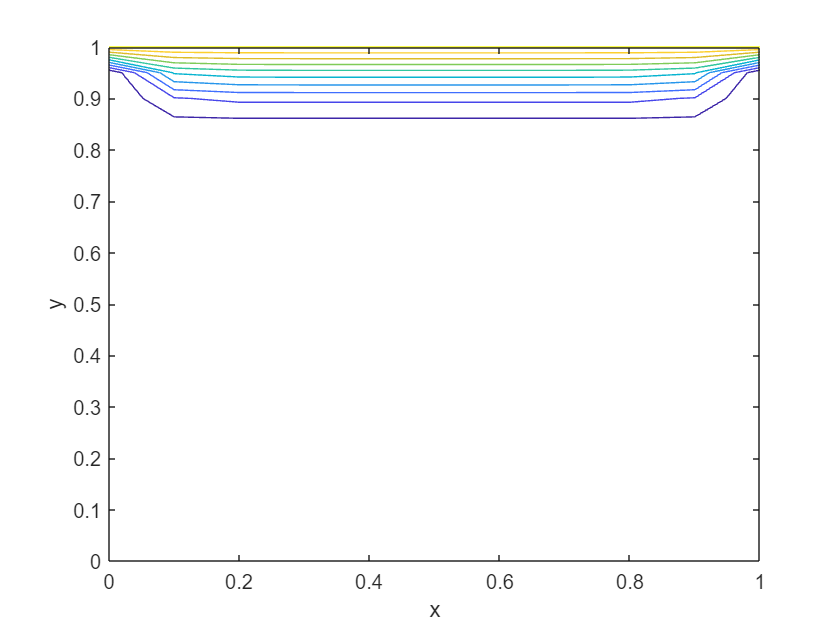

%slider
T = 0.003;
figure(4)
contour(X,Y,Z(:,:,(T*1000)+1));
xlabel('x');
ylabel('y');

References:

[1] `Elementary Numerical Analysis, Kendall Atkinson, John ``\&`` Wiley Sons Inc, 2004`